Load robot model, set joint angles for home position

clear all;
clc; 
close all;

%urdf = importrobot("C:\Users\atjensvo\cernbox\Documents\GitHub\MasterThesis\MATLAB\Collision_test.urdf", "DataFormat", "row");

% Specify Dh parameters
dhparams = [
    %a(t_x)   alpha(r_x)   d(t_z)    theta(r_z) 
    0.000     -pi/2        -0.100    0.000;      % 1 fixed body
    0.000     pi/2         10.000    0.000;      % 2 Wagon prismatic joint
    0.000     pi/2         -0.0745   0.000;      % 3 shoulder yaw   
    0.000     -pi/2        -0.183    0.000;      % 4 shoulder pitch
    0.000      0.000        0.500   -pi/2;       % 5 fixed prismatic link
    0.000      0.000        1.370    0.000;      % 6 shoulder prismatic joint
    0.150      0.000        0.000    0.000;      % 7 fixed prismatic link offset
    0.000      0.000        0.100    0.000;      % 8 first yaw joint new arm
    0.000      pi/2         0.300    0.000;      % 9 l1
    0.000      0.000        0.150    0.000;      % 10 first pitch joint
    0.000     -pi/2         0.000    0.000;      % 11 l2
    0.000     0.000         0.100    0.000;      % 12 second yaw joint
    0.000     pi/2          0.300    0.000;      % 13 l3
    0.000     0.000         0.150    0.000;      % 14 second pitch joint
    0.000     -pi/2         0.000    0.000;      % 15 l4
    0.000     0.000         0.100    0.000;      % 16 third yaw joint
    0.000     0.000         0.200    0.000;      % 17 End effector
    ];

% Define the joint types

rev = "revolute";
pris = "prismatic";
fix = "fixed";
jointTypes = [fix, pris, rev, rev, fix, pris, fix, rev, fix, rev, fix, rev, fix, rev, fix, rev, fix];

% Set home configuration
q_home = [0 -0.5*pi pi 0 0 0 0 0 0];

% Call function to create rigid body tree model

robot = createRobotModel(dhparams, jointTypes, q_home)

robot =   rigidBodyTree with properties:

     NumBodies: 17
        Bodies: {1×17 cell}
          Base: [1×1 rigidBody]
     BodyNames: {'body1'  'body2'  'body3'  'body4'  'body5'  'body6'  'body7'  'body8'  'body9'  'body10'  'body11'  'body12'  'body13'  'body14'  'body15'  'body16'  'body17'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'row'


showdetails(robot);

--------------------
Robot: (17 bodies)

 Idx     Body Name   Joint Name   Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------   ----------   ----------     ----------------   ----------------
   1         body1         jnt1        fixed              base(0)   body2(2)  
   2         body2         jnt2    prismatic             body1(1)   body3(3)  
   3         body3         jnt3     revolute             body2(2)   body4(4)  
   4         body4         jnt4     revolute             body3(3)   body5(5)  
   5         body5         jnt5        fixed             body4(4)   body6(6)  
   6         body6         jnt6    prismatic             body5(5)   body7(7)  
   7         body7         jnt7        fixed             body6(6)   body8(8)  
   8         body8         jnt8     revolute             body7(7)   body9(9)  
   9         body9         jnt9        fixed             body8(8)   body10(10)  
  10        body10        jnt10     revolute             body9(9)   body11(1


% Check for collisions in home configuration

[isColliding, sepDist, witnessPts] = checkCollision(robot, q_home);

if isColliding
    disp('The robot is in self-collision in the home configuration.');
else
    disp('No self-collision detected in the home configuration.');
end

No self-collision detected in the home configuration.


Set joint limits and show arm in home position

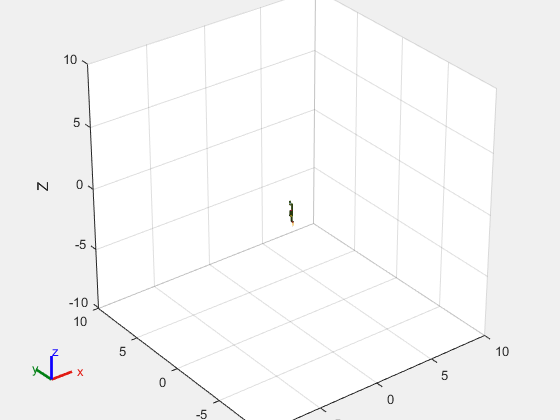

robot.getBody("body2").Joint.PositionLimits = [0, 10];
robot.getBody('body6').Joint.PositionLimits = [-0.2, 0.5];

eeName = "body17";
config = q_home;

%gui = interactiveRigidBodyTree(robot,"Configuration",q_home)
figure;
show(robot,q_home, Visuals="off", Collisions="on");
axis equal;          
xlim([-10, 10]);   
ylim([-10, 10]);      
zlim([-10, 10]);   
view(3);   
hold on

Generate environment

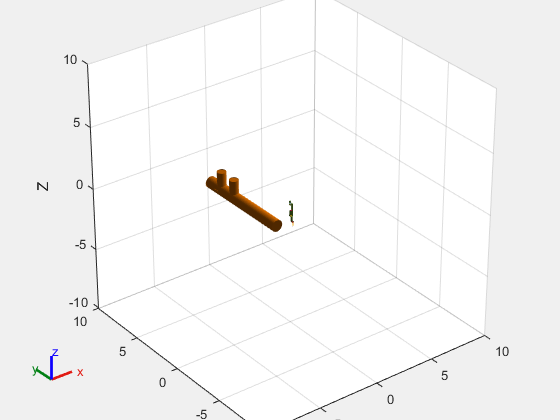

collisionCylinders = {
    collisionCylinder(0.457, 8.0),  % Main Pipe
    collisionCylinder(0.044, 0.3),  % Front BLM
    collisionCylinder(0.044, 0.3),  % Back BLM
    collisionCylinder(0.350, 1.5),  % First Obstacle
    collisionCylinder(0.350, 1.5)   % Second Obstacle
};

cylinderPoses = [
    -0.958, 4.260, -1.707, 1, 0, 0, pi/2; 
    -0.458, 2.015, -1.627, 1, 0, 0, pi/2;
    -1.456, 6.921, -1.627, 1, 0, 0, pi/2; 
    -0.952, 5.400, -0.986, 1, 0, 0, 0;
    -0.952, 6.900, -0.986, 1, 0, 0, 0
];

for i = 1:length(collisionCylinders)
    P = trvec2tform(cylinderPoses(i, 1:3));
    R = axang2tform(cylinderPoses(i, 4:7));
    collisionCylinders{i}.Pose = P * R;
    show(collisionCylinders{i});
end

Define goal poses

goalPoses = [
          -0.000, 0.000, -2.000, 0, 1, 0, pi;  % Start
          -0.476, 2.015, -1.400, 0, 1, 0, pi;  % Front BLM
          -0.000, 6.200, -2.000, 0, 1, 0, pi;  % Front Obstacles
          -1.469, 6.400, -1.400, 0, 1, 0, pi;  % Back Obstacles
          -1.469, 6.921, -1.400, 0, 1, 0, pi;  % Back BLM
            ];

disp('Plotting all target poses...');

Plotting all target poses...


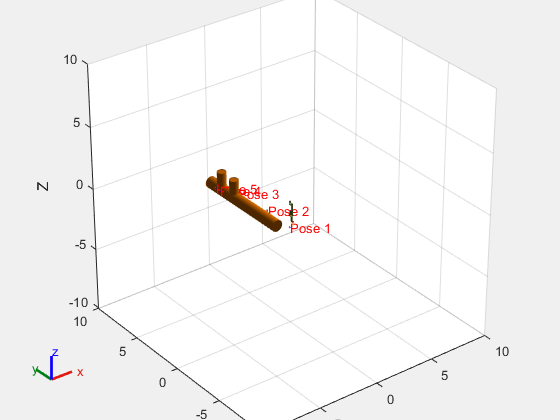

for i = 1:size(goalPoses, 1)
    pos = goalPoses(i, 1:3);
    rot = goalPoses(i, 4:7);
    poseTF = trvec2tform(pos) * axang2tform(rot);
    
    plotTransforms(pos, tform2quat(poseTF), "FrameSize", 0.1);
    text(pos(1), pos(2), pos(3), sprintf('Pose %d', i), 'FontSize', 10, 'Color', 'r');
end

Create RRT trajectory planner

planner = manipulatorRRT(robot,collisionCylinders);
planner.SkippedSelfCollisions = 'parent';
planner.EnableConnectHeuristic = true

planner =   manipulatorRRT with properties:

      MaxConnectionDistance: 0.1000
              MaxIterations: 10000
     EnableConnectHeuristic: 1
         ValidationDistance: 0.0100
    WorkspaceGoalRegionBias: 0.5000
        IgnoreSelfCollision: 0
      SkippedSelfCollisions: 'parent'


planner.MaxConnectionDistance = 0.1;
planner.ValidationDistance = 0.01;
planner.MaxIterations = 100;
rng(0)

Create IK solver

Press Enter to move to the next pose...


Pose 1 error vector: [0.0000, 0.0000, -0.0000, -0.0000, -0.0000, -0.0000]


Press Enter to move to the next pose...


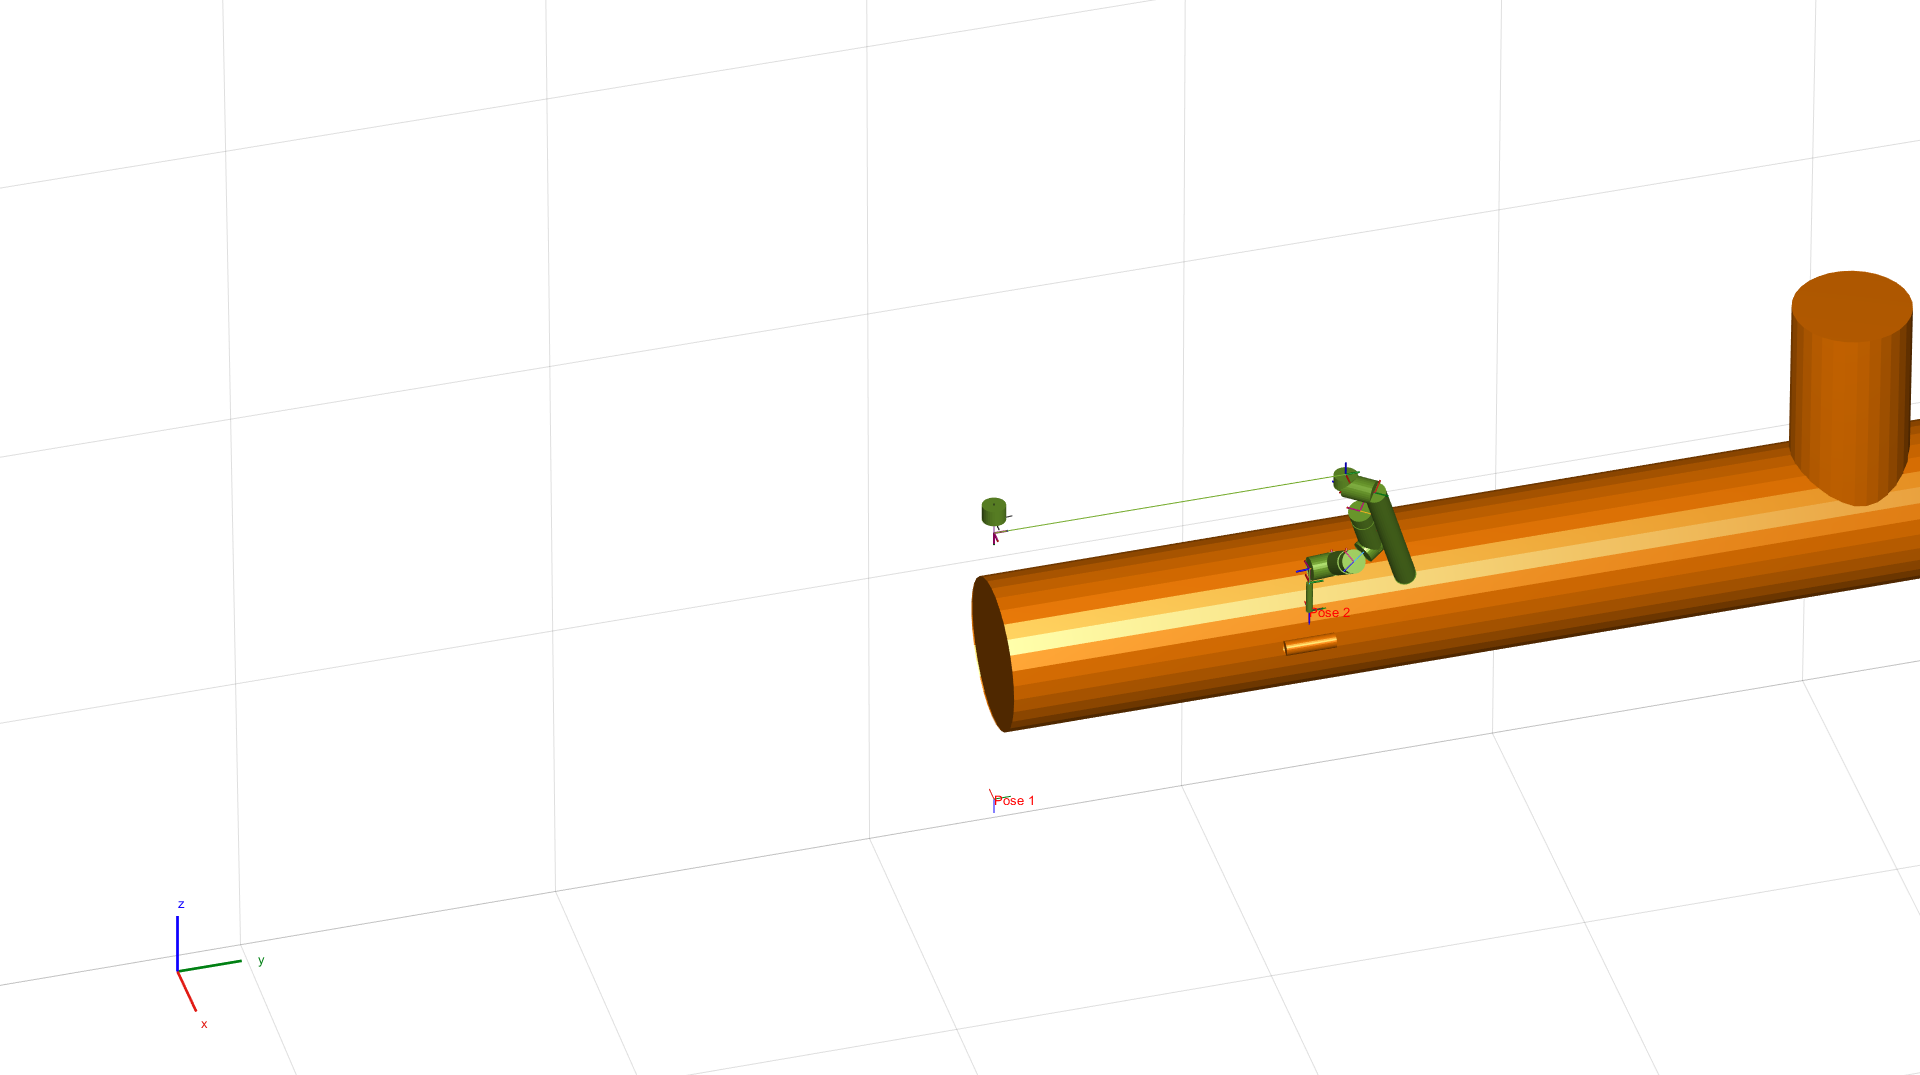

Pose 2 error vector: [-0.0000, -0.0000, 0.0000, -0.0000, -0.0000, -0.0000]


Press Enter to move to the next pose...


Pose 3 error vector: [-0.0000, -0.0000, 0.0000, -0.0000, -0.0000, 0.0000]


Press Enter to move to the next pose...


Error using robotics.manip.internal.error (line 19)
The goal configuration of the robot is in world collision.

Error in manipulatorRRT/validateInputConfiguration (line 475)
                    robotics.manip.internal.error(...

Error in 

ik = inverseKinematics('RigidBodyTree', robot);
ikWeights = [1 1 1 1 1 1];  % [orientation weights, then position weights]
qInitial = q_home;           % initial configuration as a row vector

numGoals = size(goalPoses, 1);
qSolutions = zeros(numel(q_home), numGoals);
errorVectors = zeros(6, numGoals);  % 6-element error vectors

for i = 1:numGoals
    % Wait for user input before proceeding to the next pose.
    disp('Press Enter to move to the next pose...');
    pause;
    
    % Extract the desired target pose.
    pos = goalPoses(i, 1:3);
    axang = goalPoses(i, 4:7);
    targetTform = trvec2tform(pos) * axang2tform(axang);
    
    % Compute the IK solution for the target pose.
    [qSol, solInfo] = ik(eeName, targetTform, ikWeights, qInitial);
    qSolutions(:, i) = qSol(:);  % store solution
    
    % Instead of a straight-line joint-space interpolation (which might hit collisions),
    % plan a collision-free path using the RRT planner.
    % Note: plan() expects row vectors if the robot's DataFormat is 'row'
    path = plan(planner, qInitial, qSol);  % returns a set of waypoints (each row is a configuration)
    numInterpSteps = 50;  % increase for a smoother trajectory
    q_traj = interpolate(planner, path, numInterpSteps); % q_traj is a matrix of size (numInterpSteps x nJoints)
    
    % Animate the collision-free trajectory.
    for k = 1:size(q_traj, 1)
        qCurrent = q_traj(k, :);  % row vector (1xnJoints)
        show(robot, qCurrent, 'PreservePlot', false, 'Visuals', 'off', 'Collisions', 'on');
        title(sprintf('Moving from Pose %d to Pose %d, step %d/%d', i, i, k, size(q_traj,1)));
        drawnow;
        pause(0.02);  % adjust pause for desired speed
    end
    
    % Compute the error vector at the final configuration qSol.
    T_actual = getTransform(robot, qSol, eeName);
    posDesired = tform2trvec(targetTform);
    posActual  = tform2trvec(T_actual);
    posErrorVector = posDesired - posActual;  % [ex, ey, ez]
    
    % For orientation error, compute the relative rotation.
    R_desired = tform2rotm(targetTform);
    R_actual  = tform2rotm(T_actual);
    R_err = R_actual' * R_desired;  % such that R_actual * R_err = R_desired
    axang_err = tform2axang([R_err, zeros(3,1); 0 0 0 1]);
    orientErrorVector = axang_err(1:3) * axang_err(4);  % error vector for rotation
    
    errorVector = [posErrorVector, orientErrorVector];
    errorVectors(:, i) = errorVector;
    
    fprintf('Pose %d error vector: [%.4f, %.4f, %.4f, %.4f, %.4f, %.4f]\n', ...
        i, errorVector(1), errorVector(2), errorVector(3), ...
        errorVector(4), errorVector(5), errorVector(6));
    
    % Update initial configuration for the next target pose.
    qInitial = qSol;
end